clear;clc;close all;


## Stage 0 Solar physics

kLambda = [360:10:830].'*1e-3;
kSolarIrradiance = [...
    1.11776, 1.14259, 1.01249, 1.14716, 1.72765, 1.73054, 1.6887, 1.61253,...
    1.91198, 2.03474, 2.02042, 2.02212, 1.93377, 1.95809, 1.91686, 1.8298,...
    1.8685, 1.8931, 1.85149, 1.8504, 1.8341, 1.8345, 1.8147, 1.78158, 1.7533,...
    1.6965, 1.68194, 1.64654, 1.6048, 1.52143, 1.55622, 1.5113, 1.474, 1.4482,...
    1.41018, 1.36775, 1.34188, 1.31429, 1.28303, 1.26758, 1.2367, 1.2082,...
    1.18737, 1.14683, 1.12362, 1.1058, 1.07124, 1.04992].';
kSunAngularRadius = 0.00935/2;
kSolarRadiance = kSolarIrradiance ./ (pi * kSunAngularRadius.^2);

% Stage 1: Scattering physics
Ns = 25.04;
RefractiveIndex = 1.00029;
Rscale = 6371000;
H0 = 8500/Rscale; % Atmosphere thickness, m
H1 = 1200/Rscale;
K = 2*pi^2*(RefractiveIndex^2-1)^2/3/Ns;
kRayleigh = 4*pi*K*Rscale;
kMieAngstromAlpha = 0.0;
kMieAngstromBeta = 5.328e-3;
kMieSingleScatteringAlbedo = 0.9;
kMiePhaseFunctionG = 0.8;
kMie = kMieAngstromBeta ./ H1 .* ((kLambda*1e3) .^ -kMieAngstromAlpha);

% Stage 2: Space directions
planetCenter = [0,0,0];
rGround = 1; % scaled to 1
rAtmosphere = 1.011; % scaled to 0.011

bUseCachedScatteringData = false;

% Stage 3: Setup atmosphere datastructure
atmosphere.Rg = rGround;
atmosphere.Rt = rAtmosphere;
atmosphere.sun_angular_radius = kSunAngularRadius;
atmosphere.rayleigh_density = @(h)exp(-(h)/H0);
atmosphere.rayleigh = kRayleigh;
atmosphere.rayleigh_scattering = kRayleigh ./ kLambda.^4;
atmosphere.mie_density = @(h)exp(-(h)/H1);
atmosphere.mie_scattering = kMie * kMieSingleScatteringAlbedo;
atmosphere.mie_extinction = kMie;
atmosphere.mie_phase_function_g = kMiePhaseFunctionG;
atmosphere.mu_s_min = -sqrt(1-(rGround/rAtmosphere)^2);

## Stage 3.1: Precompute optical depth

if bUseCachedScatteringData
    load("CachedScatteringData.mat")
end

if ~bUseCachedScatteringData
    u_rDist = linspace(0,1,64);
    u_muDist = linspace(0,1,256);
    [U_R0,U_MU0] = ndgrid(u_rDist, u_muDist);
    [R,MU] = RMuDecoding(atmosphere, U_R0,U_MU0);

    for i = 1:size(R,1)
        for j = 1:size(R,2)
            Transmittence = ComputeTransmittanceToTopAtmosphereBoundary(atmosphere, R(i,j), MU(i,j));
            for l = 1:numel(kLambda)
               Tex_Transmittence(i,j,l) = Transmittence(l);
            end
        end
    end

end

atmosphere.cachedTransmittence = @(u_r, u_mu)(interpn(U_R0,U_MU0,Tex_Transmittence,u_r,u_mu,'linear',0));

## 3.2 Precompute transmittence

if ~bUseCachedScatteringData
u_rDist = linspace(0,1,32);
u_muDist = [linspace(0,0.5-1e-15,64),linspace(0.5+1e-15,1,64)];
u_musDist = linspace(0,1,32);
u_nuDist = linspace(0,1,8);
[U_R,U_MU,U_MUS,U_NU] = ndgrid(u_rDist,u_muDist,u_musDist,u_nuDist);
[R,MU,MUS,NU, ~] = RMuMusNuDecoding(atmosphere, U_R, U_MU, U_MUS, U_NU);

% transmittence
[rayleigh, mie] = ComputeSingleScattering(atmosphere, ...
    R(:), MU(:), MUS(:), NU(:));
for l = 1:numel(kLambda)
    Tex_Rayleigh(:,:,:,:,l) = reshape(rayleigh(:,l), size(R));
    Tex_Mie(:,:,:,:,l) = reshape(mie(:,l), size(R));
end

save("CachedScatteringData.mat","U_R0", "U_MU0", "Tex_Transmittence", ...
    "U_R","U_MU","U_MUS","U_NU","Tex_Rayleigh", "Tex_Mie");
end

atmosphere.cachedRayleigh = @(u_r, u_mu, u_mus, u_nu)(interpn(U_R,U_MU,U_MUS,U_NU,Tex_Rayleigh,u_r,u_mu,u_mus,u_nu,'linear',0));
atmosphere.cachedMie = @(u_r, u_mu, u_mus, u_nu)(interpn(U_R,U_MU,U_MUS,U_NU,Tex_Mie,u_r,u_mu,u_mus,u_nu,'linear',0));

## Stage 4: Aerial perspective

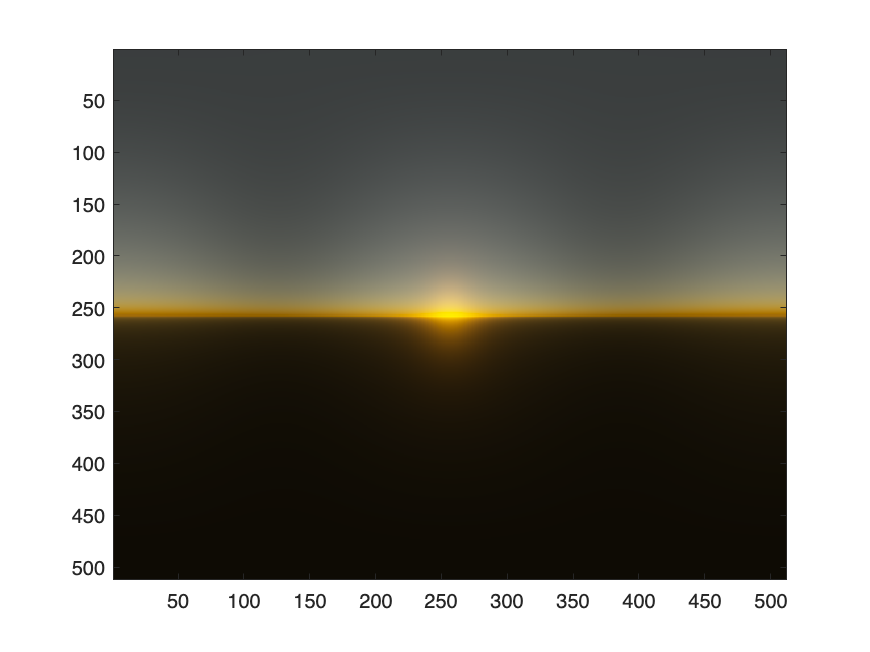

sunDir = [cosd(1.57),0,sind(1.57)];
viewPos = [0,0,1.0001];
theta = linspace(-pi, pi, 512);
phi = linspace(pi/2, -pi/2, 512);
[T, P]=meshgrid(theta, phi);
I = [];

viewDir = [];
viewDir(:,1) = cos(T(:)).*cos(P(:));
viewDir(:,2) = sin(T(:)).*cos(P(:));
viewDir(:,3) = sin(P(:));
viewPos = viewPos + 0.*T(:);

% Process indata
r = vecnorm(viewPos,2,2);
rmu = dot(viewPos,viewDir,2);

% Map to atmosphere
delta = rmu .^ 2 - r .^ 2 + atmosphere.Rt .^ 2;
distance_to_top_atmosphere_boundary = -rmu - ...
      sqrt(max(0, rmu .^ 2 - r .^ 2 + atmosphere.Rt .^ 2));
  % If the viewer is in space and the view ray intersects the atmosphere, move
  % the viewer to the top atmosphere boundary (along the view ray):
bInSpace = delta >= 0 & distance_to_top_atmosphere_boundary > 0.0;
distance_to_top_atmosphere_boundary = distance_to_top_atmosphere_boundary(bInSpace);
viewPos(bInSpace, :) = viewPos(bInSpace, :) + viewDir(bInSpace, :) .* distance_to_top_atmosphere_boundary;
r(bInSpace) = atmosphere.Rt;
rmu(bInSpace) = rmu(bInSpace) + distance_to_top_atmosphere_boundary;

mu = rmu ./ r;
mu_s = dot(viewPos, sunDir + 0*T(:),2)./vecnorm(viewPos,2,2);
nu = dot(viewDir, sunDir + 0*T(:),2);

% Compute scattering
%kSolarIrradiance = abs(randn(48,1));
I = GetScattering(r, mu, mu_s, nu, ...
    kSolarIrradiance, atmosphere, 1);

% Irradiance to RGB
Cvp = RadianceToRGB(I, kLambda);

% Tonemapping
exposure = 10/100;
Cvp = (1.0 - exp(-exposure .* max(Cvp, 0))).^(1.0/2.2);

C = [];
% Process outdata
for l = 1:3
    C(:,:,l) = reshape(Cvp(:,l), size(T,1),[]);
end

clf,figure
image(C)

%[T1,R1] = pol2cart(T, cos(P));
%warp(T1,R1,0*T1,C),view(2),shading interp,view(2),axis equal,set(gca,'color','k')
%warp(T1,R1,0*T1,tonemapfarbman(max(C,0),'Exposure',1.0)),view(2),shading interp,view(2),axis equal,set(gca,'color','k')
%image(tonemapfarbman(max(C,0),'Exposure',1.0)),shading interp

function out = GetScattering(r, mu, mu_s, nu, solarIrradiance, atmosphere, use_cache)
if use_cache
    [u_r, u_mu, u_mus, u_nu] = RMuMusNuEncoding(atmosphere, r, mu, mu_s, nu);
    rayleighScatter = squeeze(atmosphere.cachedRayleigh(u_r, u_mu, u_mus, u_nu));
    mieScatter = squeeze(atmosphere.cachedMie(u_r, u_mu, u_mus, u_nu));
else
    [rayleighScatter, mieScatter] = F_Transmittence(...
    atmosphere, ...
    r(:), mu(:), mu_s(:), nu(:));
end
for l = 1:numel(solarIrradiance)
    out(:,l) = solarIrradiance(l) .* RayleighPhaseFunction(nu) .* rayleighScatter(:,l) ...
             + solarIrradiance(l) .* MiePhaseFunction(atmosphere.mie_phase_function_g, nu) .* mieScatter(:,l);
end
end

function C = RadianceToRGB(I, lambda)
c_bar = Lambda2RGB(lambda*1e3);
C = 0*I(:,1:3);
dlambda = [0, diff(lambda.'*1e3)];
for l = 1:numel(lambda)
    C(:,1) = C(:,1) + I(:,l).*c_bar(l,1)*dlambda(l);
    C(:,2) = C(:,2) + I(:,l).*c_bar(l,2)*dlambda(l);
    C(:,3) = C(:,3) + I(:,l).*c_bar(l,3)*dlambda(l);
end
end